# ÁTOMO DE HELIO

## **1. FUNCION DE TIPO GAUSSIANA TRIVIAL** 

### 1.1. MÉTODO DE VARIACIONES LINEALES (Aproximación Vee)

clc; clear;
syms b r1 r2 r12 theta positive
assumeAlso(b > 0 & r1 > 0 & r2 > 0 & r12 > 0)
%sympref('default');
fprintf('---------------------------------------------------------------------\n\n')
fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---\n\n');

% === Paso 1: Definir funciones base ===

---------------------------------------------------------------------



% Para helio, usamos funciones gaussianas para cada electrón

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---



phi_r1 = exp(-b * r1^2);  % Función gaussiana para el primer electrón
phi_r2 = exp(-b * r2^2);  % Función gaussiana para el segundo electrón


% === Paso 2: Normalización de la función base ===
fprintf('--- Paso 1: Normalización de la función base ---\n');
norm_phi = int(phi_r1^2 * r1^2 * 4*pi, r1, 0, inf);
A = simplify(1 / sqrt(norm_phi));
fprintf('\n A:\n'); disp(A);

--- Paso 1: Normalización de la función base ---




% Función normalizada para cada electrón


 A:


$$\frac{2^{3/4}\,b^{3/4}}{\pi^{3/4}}$$

phi_r1_norm = A * phi_r1;
phi_r2_norm = A * phi_r2;

% Función de onda total (producto)
psi_total = phi_r1_norm * phi_r2_norm;
fprintf('\nFunción de onda total ψ(r1,r2):\n'); disp(psi_total);
fprintf('Que corresponde a: A^2 * e^(-b*(r1^2+r2^2))\n');

% Guardar como celda para uso matricial posterior


Función de onda total ψ(r1,r2):


$$\frac{2\,\sqrt{2}\,b^{3/2}\,{\mathrm{e}}^{-b\,{r_{1}}^{2}}\,{\mathrm{e}}^{-b\,{r_{2}}^{2}}}{\pi^{3/2}}$$

f_base{1} = psi_total;

Que corresponde a: A^2 * e^(-b*(r1^2+r2^2))


f_norm{1} = psi_total;
n = 1;

% === Paso 3: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');
S = sym(zeros(n));
for i = 1:n
    for j = 1:n


--- Paso 2: Matriz de solapamiento S ---


        integrand_S = f_norm{i} * f_norm{j} * r1^2 * r2^2 * (4*pi)^2;
        S(i,j) = simplify(int(int(integrand_S, r1, 0, inf), r2, 0, inf));

    end
end
disp(double(S));

% === Paso 4: Matriz Hamiltoniana H = T + V_en + V_ee ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');

    1.0000



H = sym(zeros(n));
for i = 1:n
    for j = 1:n


--- Paso 3: Matriz Hamiltoniana H ---


        psi_i = f_norm{i};
        psi_j = f_norm{j};

        % === Término cinético: T = -1/2 (Δ1 + Δ2)
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;

        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;

        % Usar el elemento de volumen correcto (4*pi)^2
        T_integrand = psi_i * (-0.5) * (lap1 + lap2) * r1^2 * r2^2 * (4*pi)^2;
        T = simplify(int(int(T_integrand, r1, 0, inf), r2, 0, inf));
        fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(vpa(T,2));

        % === Término V_en: V_en = -2/r1 - 2/r2 (Z=2 para helio)
        V_en = -2/r1 - 2/r2;
        % Usar el elemento de volumen correcto (4*pi)^2
        V_integrand = psi_i * psi_j * V_en * r1^2 * r2^2 * (4*pi)^2;
        V = simplify(int(int(V_integrand, r1, 0, inf), r2, 0, inf));
        fprintf('Término V_en(%d,%d):\n', i, j); disp(vpa(V,2));
           
        % Para gaussianas, la integral se puede aproximar como:
        V_ee = (sqrt(pi)/2) * (1/sqrt(b));
        fprintf('Término V_en(%d,%d):\n', i, j); disp(vpa(V_ee,2));

            
        H(i,j) = simplify(T + V + V_ee);
        fprintf('H(%d,%d) = T + V_en + V_ee:\n', i, j); disp(vpa(H(i,j),2));
    end
end


% === Paso 5: Resolver Hc = ESc ===


Término cinético T(1,1):


$$3.0\,b$$

Término V_en(1,1):


$$-6.4\,\sqrt{b}$$

Término V_en(1,1):


$$\frac{0.89}{\sqrt{b}}$$

H(1,1) = T + V_en + V_ee:


$$3.0\,b+\frac{0.89}{\sqrt{b}}-6.4\,\sqrt{b}$$

fprintf('\n--- Paso 4: Resolviendo H c = E S c ---\n');
syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);


--- Paso 4: Resolviendo H c = E S c ---


Energies = simplify(Energies);
disp('Energías obtenidas simbólicamente:');
disp(vpa(Energies,2));

% === Paso 6: Derivar y encontrar mínimo respecto a b ===

Energías obtenidas simbólicamente:


fprintf('\n--- Paso 5: Optimización del parámetro b ---\n');

$$\frac{1.3e-17\,\left(2.4e+17\,b^{3/2}-5.0e+17\,b+7.0e+16\right)}{\sqrt{b}}$$

for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    dE = simplify(diff(Energies(k), b));


--- Paso 5: Optimización del parámetro b ---


    fprintf('Derivada dE/db:\n'); disp(vpa(dE,2));

    b_sol = solve(dE == 0, b);
    b_sol = simplify(b_sol(b_sol > 0));
    fprintf('b óptimo para E_%d:\n', k); disp(vpa(b_sol,2));

    E_min = simplify(subs(Energies(k), b, b_sol));
    fprintf('Energía óptima (Hartree):\n'); disp(vpa(E_min,2));
    fprintf('Energía óptima (eV): %.4f\n', double(E_min * 27.2114));
end
% Guardar el valor óptimo de b para la visualización
b_opt = b_sol;



>> Energía E_1:


Derivada dE/db:


$$-\frac{6.3e-18\,\left(5.0e+17\,b-4.7e+17\,b^{3/2}+7.0e+16\right)}{b^{3/2}}$$

b óptimo para E_1:


$$1.4$$

Energía óptima (Hartree):


$$-2.6$$

Energía óptima (eV): -70.8598


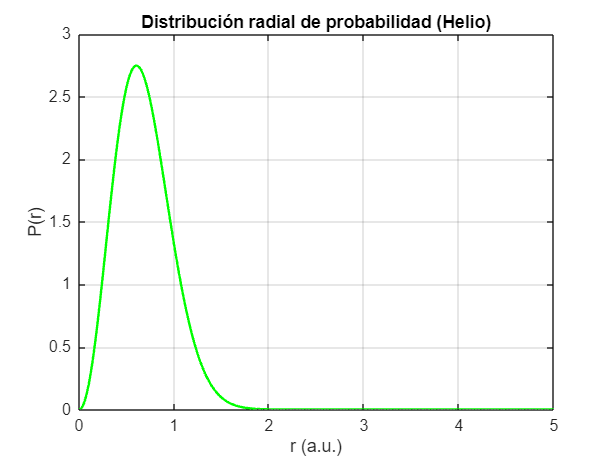

% ==================== VISUALIZACIÓN Y RESULTADOS (helio) =============
hartree_to_eV = 27.2114;
E_exp_eV      = -79.0;      % Energía experimental (eV)
E_exp_H       = E_exp_eV/hartree_to_eV;

% Parámetros
r_vals     = linspace(0,5,400);
b_opt_num  = double(b_opt(1));
A_num      = double(subs(A, b, b_opt_num));

% --- 1) Densidad radial marginal (2 electrones) ----------------------------
phi_vals   = A_num .* exp(-b_opt_num .* r_vals.^2);          % orbital 1e
rho_vals   = 2 .* phi_vals.^2;                               % densidad un–electrón marginal
P_rad      = 4*pi .* r_vals.^2 .* rho_vals;                  % distribución radial real

figure(1);
plot(r_vals, P_rad, 'g', 'LineWidth',1.5);
xlabel('r (a.u.)'); ylabel('P(r)');
title('Distribución radial de probabilidad (Helio)'); %marginal
grid on;

% --- 2) Sección diagonal de psi_tot y su distribución ----------------------
psi_tot_diag    = A_num^2 .* exp(-2*b_opt_num .* r_vals.^2);

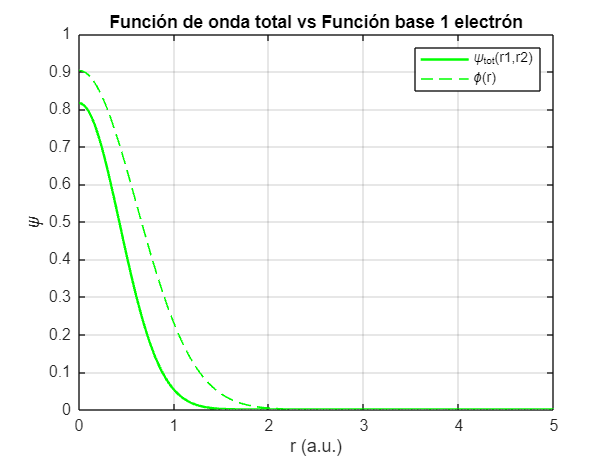

rho_tot_diag   = psi_tot_diag.^2;
P_tot_diag      = 4*pi .* r_vals.^2 .* rho_tot_diag;

figure(2);
plot(r_vals, psi_tot_diag, 'g', 'LineWidth',1.5);
hold on;
plot(r_vals, phi_vals, 'g--', 'LineWidth',1);
hold off;
xlabel('r (a.u.)'); ylabel('\psi');
legend('\psi_{tot}(r1,r2)','\phi(r)');
title('Función de onda total vs Función base 1 electrón');
grid on;


% --- 4) Energía vs b -------------------------------------------------------

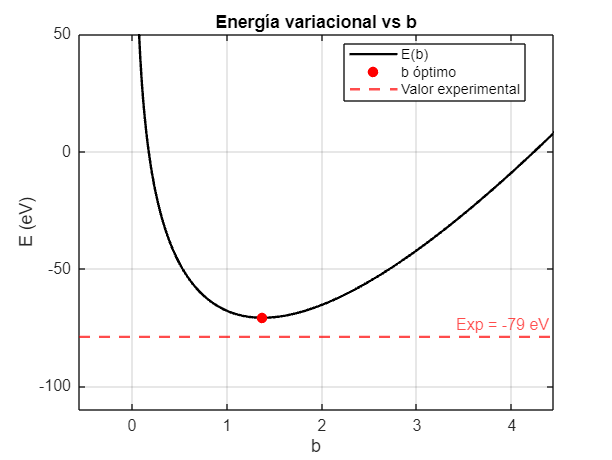

b_scan   = linspace(0.05,5,300);
E_scan   = arrayfun(@(bb) double(subs(Energies(1), b, bb)), b_scan);
E_scan_eV= E_scan * hartree_to_eV;
E1_H     = double(subs(Energies(1), b, b_opt_num));
E1_eV    = E1_H * hartree_to_eV;

figure(5);
plot(b_scan, E_scan_eV, 'k', 'LineWidth',1.5); hold on;
plot(b_opt_num, E1_eV, 'ro','MarkerFaceColor','r');
yline(E_exp_eV,'r--','Exp = -79 eV','LineWidth',1.5);
hold off;
xlabel('b'); ylabel('E (eV)');
title('Energía variacional vs b');
legend('E(b)','b óptimo','Valor experimental','Location','best');
grid on;

xlim([-0.56 4.44])
ylim([-110 50])

% --- 5) Resultados y errores -----------------------------------------------
fprintf('\n=== RESULTADOS HELIO ===\n');

fprintf('b óptimo        : %.4f\n', b_opt_num);
fprintf('E calculada     : %.4f eV (%.4f Ha)\n', E1_eV, E1_H);
fprintf('E experimental  : %.4f eV (%.4f Ha)\n', E_exp_eV, E_exp_H);


=== RESULTADOS HELIO ===


err_eV  = abs(E1_eV - E_exp_eV); 

b óptimo        : 1.3724


err = err_eV/abs(E_exp_eV)*100;

E calculada     : -70.8598 eV (-2.6040 Ha)


fprintf('Error absoluto (eV) : %.4f\n', err_eV);

E experimental  : -79.0000 eV (-2.9032 Ha)


fprintf('Error relativo      : %.2f %%\n', err);



Error absoluto (eV) : 8.1402


Error relativo      : 10.30 %


## 2. FUNCIÓN ÁTOMO HIDROGENOIDE (parámetro z)

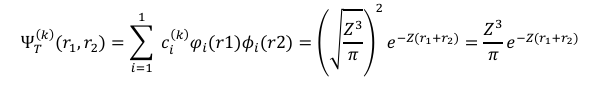

### 2.1. MÉTODO DE VARIACIONES LINEALES (Aproximación Vee)

clc; clear;
syms Z r1 r2 r12 theta positive
assumeAlso(Z > 0 & r1 > 0 & r2 > 0 & r12 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---


fprintf('--- USANDO FUNCIONES HIDROGENOIDES Y APROXIMACIÓN VEE ---\n\n');

--- USANDO FUNCIONES HIDROGENOIDES Y APROXIMACIÓN VEE ---




% === Paso 1: Definir funciones base ===
% Para helio, usamos funciones hidrogenoides para cada electrón
% ψ(r) = √(Z³/πa₀³) e^(-Zr/a₀), donde Z es el parámetro variacional
% En unidades atómicas a₀ = 1
fprintf('--- Paso 1: Definir funciones base ---\n');

--- Paso 1: Definir funciones base ---


phi_r1 = sqrt(Z^3/pi) * exp(-Z*r1);  % Función hidrogenoide para el primer electrón
phi_r2 = sqrt(Z^3/pi) * exp(-Z*r2);  % Función hidrogenoide para el segundo electrón
fprintf('Función base para el primer electrón: √(Z³/π) * e^(-Z*r1)\n');

Función base para el primer electrón: √(Z³/π) * e^(-Z*r1)


fprintf('Función base para el segundo electrón: √(Z³/π) * e^(-Z*r2)\n\n');

Función base para el segundo electrón: √(Z³/π) * e^(-Z*r2)




% Las funciones hidrogenoides ya están normalizadas, por lo que A = 1
A = 1;
fprintf('Las funciones hidrogenoides ya están normalizadas (A = 1)\n');

Las funciones hidrogenoides ya están normalizadas (A = 1)



% Función de onda total (producto)
psi_total = phi_r1 * phi_r2;
fprintf('\nFunción de onda total ψ(r1,r2):\n'); disp(psi_total);


Función de onda total ψ(r1,r2):


$$\frac{Z^{3}\,{\mathrm{e}}^{-Z\,r_{1}}\,{\mathrm{e}}^{-Z\,r_{2}}}{\pi }$$

fprintf('Que corresponde a: (Z³/π) * e^(-Z*(r1+r2))\n');

Que corresponde a: (Z³/π) * e^(-Z*(r1+r2))



% Guardar como celda para uso matricial posterior
f_base{1} = psi_total;
f_norm{1} = psi_total;
n = 1;

% === Paso 2: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        integrand_S = f_norm{i} * f_norm{j} * r1^2 * r2^2 * (4*pi)^2;
        S(i,j) = simplify(int(int(integrand_S, r1, 0, inf), r2, 0, inf));
    end
end
disp(double(S));

    1.0000




% === Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');


--- Paso 3: Matriz Hamiltoniana H ---


H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        psi_i = f_norm{i};
        psi_j = f_norm{j};

        % === Término cinético: T = -1/2 (Δ1 + Δ2)
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;

        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;

        % Usar el elemento de volumen correcto (4*pi)^2
        T_integrand = psi_i * (-0.5) * (lap1 + lap2) * r1^2 * r2^2 * (4*pi)^2;
        T = simplify(int(int(T_integrand, r1, 0, inf), r2, 0, inf));
        fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(vpa(T,2));

        % === Término V_en: V_en = -2/r1 - 2/r2 (Z=2 para helio)
        V_en = -2/r1 - 2/r2;
        % Usar el elemento de volumen correcto (4*pi)^2
        V_integrand = psi_i * psi_j * V_en * r1^2 * r2^2 * (4*pi)^2;
        V = simplify(int(int(V_integrand, r1, 0, inf), r2, 0, inf));
        fprintf('Término V_en(%d,%d):\n', i, j); disp(vpa(V,2));
           
        % Para funciones hidrogenoides, la integral se puede calcular como:
        % Aproximación para la repulsión electrón-electrón
        V_ee = 5*Z/8;
        fprintf('Término V_ee(%d,%d):\n', i, j); disp(vpa(V_ee,2));
            
        H(i,j) = simplify(T + V + V_ee);
        fprintf('H(%d,%d) = T + V_en + V_ee:\n', i, j); disp(vpa(H(i,j),2));
    end
end


Término cinético T(1,1):


$$1.0\,Z^{2}$$

Término V_en(1,1):


$$-4.0\,Z$$

Término V_ee(1,1):


$$0.62\,Z$$

H(1,1) = T + V_en + V_ee:


$$1.8e-15\,Z\,\left(5.6e+14\,Z-1.9e+15\right)$$


% === Paso 4: Resolver Hc = ESc ===
fprintf('\n--- Paso 4: Resolviendo H c = E S c ---\n');


--- Paso 4: Resolviendo H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);
disp('Energías obtenidas simbólicamente:');

Energías obtenidas simbólicamente:


disp(vpa(Energies,2));

$$Z^{2}-3.4\,Z$$


% === Paso 5: Derivar y encontrar mínimo respecto a Z ===
fprintf('\n--- Paso 5: Optimización del parámetro Z ---\n');


--- Paso 5: Optimización del parámetro Z ---


for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    dE = simplify(diff(Energies(k), Z));
    fprintf('Derivada dE/dZ:\n'); disp(vpa(dE,2));

    Z_sol = solve(dE == 0, Z);
    Z_sol = simplify(Z_sol(Z_sol > 0));
    fprintf('Z óptimo para E_%d:\n', k); disp(vpa(Z_sol,2));

    E_min = simplify(subs(Energies(k), Z, Z_sol));
    fprintf('Energía óptima (Hartree):\n'); disp(vpa(E_min,2));
    fprintf('Energía óptima (eV): %.4f\n', double(E_min * 27.2114));
end


>> Energía E_1:


Derivada dE/dZ:


$$2.0\,Z-3.4$$

Z óptimo para E_1:


$$1.7$$

Energía óptima (Hartree):


$$-2.8$$

Energía óptima (eV): -77.4887


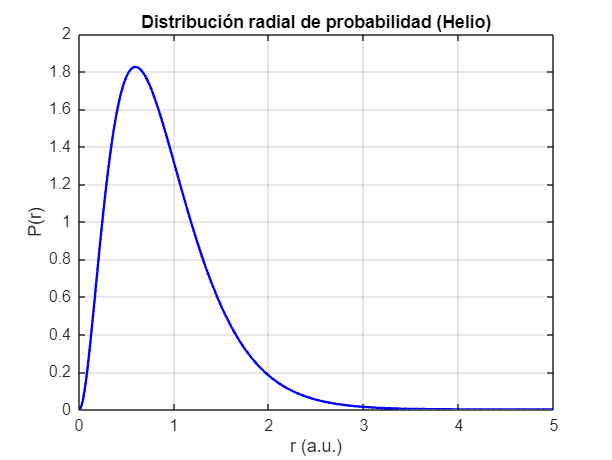


% Guardar el valor óptimo de Z para la visualización
Z_opt = Z_sol;

% ==================== VISUALIZACIÓN Y RESULTADOS (Helio – funciones hidrogenoides) =========
hartree_to_eV = 27.2114;
E_exp_eV      = -79.0;               % Energía experimental (eV)
E_exp_H       = E_exp_eV / hartree_to_eV;

% Parámetros variacionales optimizados
Z_opt_num = double(Z_opt);           % Z óptimo
phi0      = sqrt(Z_opt_num^3/pi);    % Normalización de la base hidrogenoide

% Dominio radial
r_vals = linspace(0, 5, 400);

% 1) Distribución radial marginal (dos electrones)
phi_vals = phi0 .* exp(-Z_opt_num .* r_vals);   % φ(r) del orbital
rho_vals = 2 .* phi_vals.^2;                    % densidad marginal un–electrón
P_rad    = 4*pi .* r_vals.^2 .* rho_vals;       % probabilidad radial real

figure(1);
plot(r_vals, P_rad, 'b', 'LineWidth', 1.5);
xlabel('r (a.u.)'); ylabel('P(r)');
title('Distribución radial de probabilidad (Helio)');
grid on;

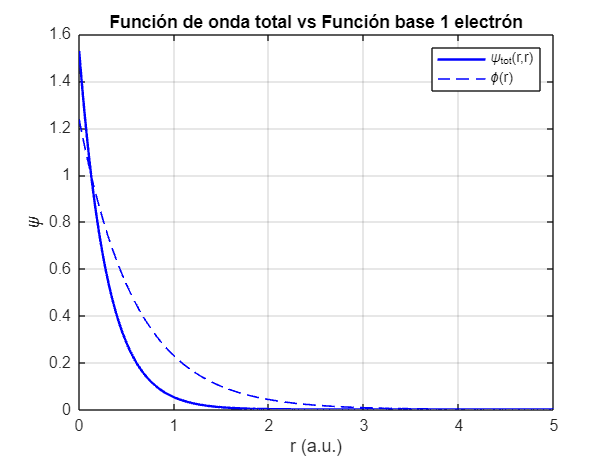

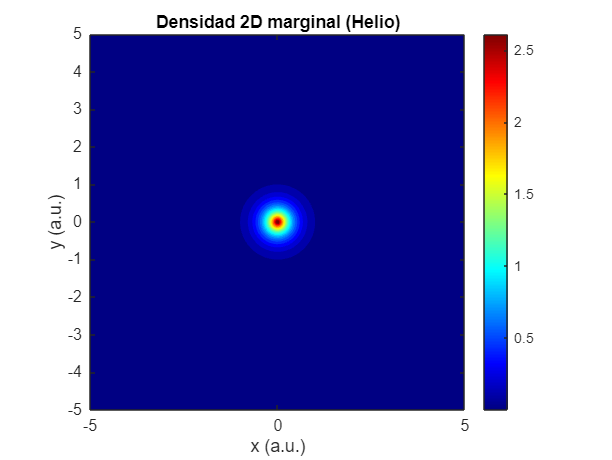


% 2) Onda total en la diagonal vs orbital un–electrón
psi_tot_diag = phi0^2 .* exp(-2*Z_opt_num .* r_vals);

figure(2);
plot(r_vals, psi_tot_diag, 'b', 'LineWidth', 1.5); hold on;
plot(r_vals, phi_vals,       'b--','LineWidth', 1);
hold off;
xlabel('r (a.u.)'); ylabel('\psi');
legend('\psi_{tot}(r,r)','\phi(r)','Location','northeast');
title('Función de onda total vs Función base 1 electrón');
grid on;

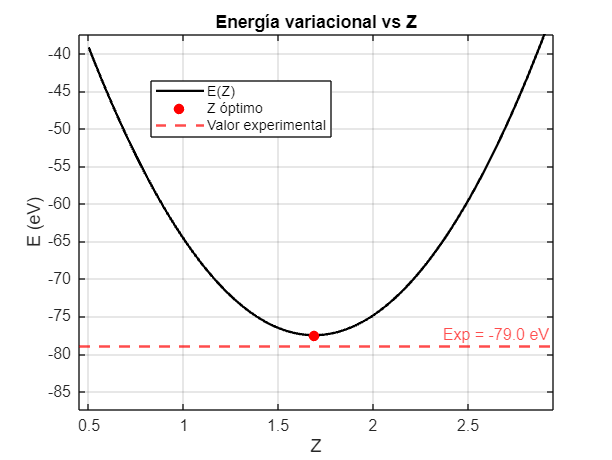


% 4) Energía variacional vs Z
Z_scan    = linspace(0.5, 3, 300);
E_scan    = arrayfun(@(Zt) double(subs(Energies(1), Z, Zt)), Z_scan);
E_scan_eV = E_scan * hartree_to_eV;
E1_H      = double(subs(Energies(1), Z, Z_opt_num));
E1_eV     = E1_H * hartree_to_eV;

figure(4);

plot(Z_scan, E_scan_eV, 'k', 'LineWidth', 1.5); hold on;
plot(Z_opt_num, E1_eV, 'ro','MarkerFaceColor','r');
yline(E_exp_eV, 'r--', 'Exp = -79.0 eV', 'LineWidth', 1.5);
hold off;
xlabel('Z'); ylabel('E (eV)');
title('Energía variacional vs Z');
legend('E(Z)', 'Z óptimo', 'Valor experimental','Location','best');
grid on;

xlim([0.45 2.95])
ylim([-87.4 -37.4])

legend(["E(Z)", "Z óptimo", "Valor experimental"], "Position", [0.2602 0.7089 0.2696, 0.1119])


% 5) Impresión de resultados y errores
fprintf('\n=== RESULTADOS HELIO (HIDROGENOIDE) ===\n');


=== RESULTADOS HELIO (HIDROGENOIDE) ===


fprintf('Z óptimo        : %.4f\n', Z_opt_num);

Z óptimo        : 1.6875


fprintf('E calculada     : %.4f eV (%.4f Ha)\n', E1_eV, E1_H);

E calculada     : -77.4887 eV (-2.8477 Ha)


fprintf('E experimental  : %.4f eV (%.4f Ha)\n', E_exp_eV, E_exp_H);

E experimental  : -79.0000 eV (-2.9032 Ha)



err_eV  = abs(E1_eV - E_exp_eV);
err_rel = err_eV / abs(E_exp_eV) * 100;
fprintf('Error absoluto (eV) : %.4f\n', err_eV);

Error absoluto (eV) : 1.5113


fprintf('Error relativo      : %.2f %%\n', err_rel);

Error relativo      : 1.91 %


### 2.2.  MÉTODO DE VARIACIONES LINEALES (Sin aproximación Vee, desarrollando integrales)


clc; clear;
syms Z r1 r2 r12 theta positive
assumeAlso(Z > 0 & r1 > 0 & r2 > 0 & r12 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---


fprintf('--- USANDO FUNCIONES HIDROGENOIDES SIN APROXIMACIÓN VEE ---\n\n');

--- USANDO FUNCIONES HIDROGENOIDES SIN APROXIMACIÓN VEE ---




% === Paso 1: Definir funciones base ===
fprintf('--- Paso 1: Definir funciones base ---\n');

--- Paso 1: Definir funciones base ---


phi_r1 = sqrt(Z^3/pi) * exp(-Z*r1);  % Función hidrogenoide para el primer electrón
phi_r2 = sqrt(Z^3/pi) * exp(-Z*r2);  % Función hidrogenoide para el segundo electrón
fprintf('Función base para el primer electrón: √(Z³/π) * e^(-Z*r1)\n');

Función base para el primer electrón: √(Z³/π) * e^(-Z*r1)


fprintf('Función base para el segundo electrón: √(Z³/π) * e^(-Z*r2)\n\n');

Función base para el segundo electrón: √(Z³/π) * e^(-Z*r2)




% Las funciones hidrogenoides ya están normalizadas, por lo que A = 1
A = 1;
fprintf('Las funciones hidrogenoides ya están normalizadas (A = 1)\n');

Las funciones hidrogenoides ya están normalizadas (A = 1)



% Función de onda total (producto)
psi_total = phi_r1 * phi_r2;
fprintf('\nFunción de onda total ψ(r1,r2):\n'); disp(psi_total);


Función de onda total ψ(r1,r2):


$$\frac{Z^{3}\,{\mathrm{e}}^{-Z\,r_{1}}\,{\mathrm{e}}^{-Z\,r_{2}}}{\pi }$$

fprintf('Que corresponde a: (Z³/π) * e^(-Z*(r1+r2))\n');

Que corresponde a: (Z³/π) * e^(-Z*(r1+r2))



% Guardar como celda para uso matricial posterior
f_base{1} = psi_total;
f_norm{1} = psi_total;
n = 1;

% === Paso 2: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        integrand_S = f_norm{i} * f_norm{j} * r1^2 * r2^2 * (4*pi)^2;
        S(i,j) = simplify(int(int(integrand_S, r1, 0, inf), r2, 0, inf));
    end
end
disp(double(S));

    1.0000




% === Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');


--- Paso 3: Matriz Hamiltoniana H ---


H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        psi_i = f_norm{i};
        psi_j = f_norm{j};

        % === Término cinético: T = -1/2 (Δ1 + Δ2)
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;

        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;

        % Usar el elemento de volumen correcto (4*pi)^2
        T_integrand = psi_i * (-0.5) * (lap1 + lap2) * r1^2 * r2^2 * (4*pi)^2;
        T = simplify(int(int(T_integrand, r1, 0, inf), r2, 0, inf));
        %fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(vpa(T,2));

        % === Término V_en: V_en = -2/r1 - 2/r2 (Z=2 para helio)
        V_en = -2/r1 - 2/r2;
        % Usar el elemento de volumen correcto (4*pi)^2
        V_integrand = psi_i * psi_j * V_en * r1^2 * r2^2 * (4*pi)^2;
        V = simplify(int(int(V_integrand, r1, 0, inf), r2, 0, inf));
        %fprintf('Término V_en(%d,%d):\n', i, j); disp(vpa(V,2));
        
        % === Término V_ee: Repulsión electrón-electrón ===
        %fprintf('Calculando V_ee mediante integración completa...\n');
        
        % Definir variables simbólicas para las integrales
        syms r2_var r1_var theta_var real positive
        
        % Parámetro a para las integrales (2Z para funciones hidrogenoides)
        a = 2*Z;
        
        % Densidad de probabilidad |psi|^2
        psi_squared = (psi_i * psi_j)^2;
        
        % Distancia entre electrones r12
        r12_expr = sqrt(r1^2 + r2^2 - 2*r1*r2*cos(theta));
        
        % 1. Integral angular IA (sin(theta)/r12)
        IA_integrand = sin(theta_var)/sqrt(r1^2 + r2^2 - 2*r1*r2*cos(theta_var));
        IA = int(IA_integrand, theta_var, 0, pi);
        
        % 2. Integral IB (para r2 < r1)
        IB_integrand = r2_var^2 * exp(-a*r2_var);
        IB_integral = int(IB_integrand, r2_var, 0, r1_var);
        IB = 2/r1_var * IB_integral;
        
        % 3. Integral IC (para r2 > r1)
        IC_integrand = r2_var * exp(-a*r2_var);
        IC_integral = int(IC_integrand, r2_var, r1_var, inf);
        IC = 2 * IC_integral;
        
        % 4. Combinar en el integrando final
        integrand_Vee = r1_var^2 * exp(-a*r1_var) * (IB + IC);
        
        % 5. Constante multiplicativa
        const = 8 * pi^2 * (Z^3/pi)^2;
        
        % 6. Integral final para V_ee
        Vee_integral = const * int(integrand_Vee, r1_var, 0, inf);
        V_ee = simplify(Vee_integral);
        
        %fprintf('Término V_ee(%d,%d):\n', i, j); disp(vpa(V_ee,2));
            
        H(i,j) = simplify(T + V + V_ee);
        %fprintf('H(%d,%d) = T + V_en + V_ee:\n', i, j); disp(vpa(H(i,j),2));
    end
end
disp(H)

$$\frac{2778046668940015\,Z\,\left(8\,Z-27\right)}{2251799813685248\,\pi^{2}}$$


% === Paso 4: Resolver Hc = ESc ===
fprintf('\n--- Paso 4: Resolviendo H c = E S c ---\n');


--- Paso 4: Resolviendo H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);
%disp('Energías obtenidas simbólicamente:');
%disp(vpa(Energies,2));

% === Paso 5: Derivar y encontrar mínimo respecto a Z ===
fprintf('\n--- Paso 5: Optimización del parámetro Z ---\n');


--- Paso 5: Optimización del parámetro Z ---


for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    dE = simplify(diff(Energies(k), Z));
    %fprintf('Derivada dE/dZ:\n'); disp(vpa(dE,2));

    Z_sol = solve(dE == 0, Z);
    Z_sol = simplify(Z_sol(Z_sol > 0));
    fprintf('Z óptimo para E_%d:\n', k); disp(vpa(Z_sol,2));

    E_min = simplify(subs(Energies(k), Z, Z_sol));
    fprintf('Energía óptima (Hartree):\n'); disp(vpa(E_min,2));
    fprintf('Energía óptima (eV): %.4f\n', double(E_min * 27.2114));
end


>> Energía E_1:


Z óptimo para E_1:


$$1.7$$

Energía óptima (Hartree):


$$-2.8$$

Energía óptima (eV): -77.4887



% Guardar el valor óptimo de Z para la visualización
Z_opt = Z_sol;

% --- (tras haber calculado Z_opt, Energies, etc.) ---

% Recalcular energía para Z_opt
hartree_to_eV = 27.2114;
E1_H  = double(subs(Energies(1), Z, Z_opt));  % en Hartree
E1_eV = E1_H * hartree_to_eV;                 % en eV

% Parámetros experimentales
E_exp_eV = -79.0;
E_exp_H  = E_exp_eV / hartree_to_eV;

% Errores
err_abs_eV = abs(E1_eV - E_exp_eV);
err_rel_pct = err_abs_eV / abs(E_exp_eV) * 100;

% Imprimir por pantalla 
fprintf('\n=== RESULTADOS HELIO (HIDROGENOIDE) ===\n');


=== RESULTADOS HELIO (HIDROGENOIDE) ===


fprintf('Z óptimo        : %.4f\n', Z_opt);

Z óptimo        : 1.6875


fprintf('E calculada     : %.4f eV (%.4f Ha)\n', E1_eV, E1_H);

E calculada     : -77.4887 eV (-2.8477 Ha)


fprintf('E experimental  : %.4f eV (%.4f Ha)\n', E_exp_eV, E_exp_H);

E experimental  : -79.0000 eV (-2.9032 Ha)


fprintf('Error absoluto (eV) : %.4f\n', err_abs_eV);

Error absoluto (eV) : 1.5113


fprintf('Error relativo      : %.2f %%\n', err_rel_pct);

Error relativo      : 1.91 %


## 3. ESTADOS EXCITADOS FUNCIONES HIDROGENOIDES

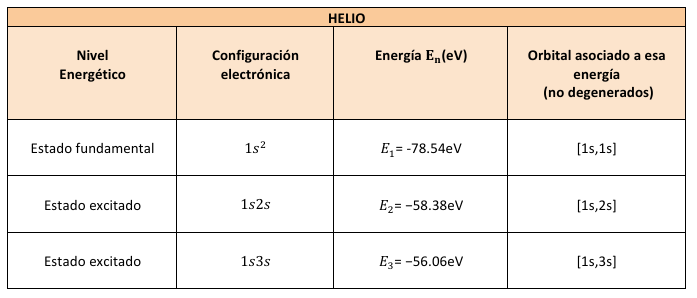

Cada una de  estas funciones base Ψ𝑖(𝑟1,𝑟2) se forma utilizando funciones radiales hidrogenoides


clc; clear;
syms Z r1 r2 positive
assumeAlso(Z > 0 & r1 > 0 & r2 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---


fprintf('--- USANDO FUNCIONES HIDROGENOIDES PARA ESTADO FUNDAMENTAL Y FUNCIONES RADIALES HIDROGENOIDES EXCITADOS ---\n\n');

--- USANDO FUNCIONES HIDROGENOIDES PARA ESTADO FUNDAMENTAL Y EXCITADOS ---




% === Paso 1: Definir funciones base ===
fprintf('--- Paso 1: Definir funciones base ---\n');

--- Paso 1: Definir funciones base ---



% Funciones base para el primer electrón (1s, 2s, 3s)
phi1_1s = sqrt(Z^3/pi) * exp(-Z*r1);
phi1_2s = sqrt(Z^3/(8)) * (2-Z*r1) * exp(-Z*r1/2);
phi1_3s = (2/27)*sqrt(Z^3/27) * (27-18*Z*r1+2*Z^2*r1^2) * exp(-Z*r1/3);

% Funciones base para el segundo electrón (1s, 2s, 3s)
phi2_1s = sqrt(Z^3/pi) * exp(-Z*r2);
phi2_2s = sqrt(Z^3/(8)) * (2-Z*r2) * exp(-Z*r2/2);
phi2_3s = (2/27)*sqrt(Z^3/27) * (27-18*Z*r2+2*Z^2*r2^2) * exp(-Z*r2/3);



% Construir funciones de onda totales (productos)
f_base = cell(1, 3);
f_base{1} = phi1_1s * phi2_1s;  % Estado 1s²
f_base{2} = (phi1_1s * phi2_2s + phi1_2s * phi2_1s)/sqrt(2);  % Estado 1s2s (simetrizado)
f_base{3} = (phi1_1s * phi2_3s + phi1_3s * phi2_1s)/sqrt(2);  % Estado 1s3s (simetrizado)


f_norm = f_base;

% === Paso 2: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(3));

for i = 1:3
    for j = 1:3
        integrand_S = f_norm{i} * f_norm{j} * r1^2 * r2^2 * (4*pi)^2;
        S(i,j) = simplify(int(int(integrand_S, r1, 0, inf), r2, 0, inf));
    end
end

fprintf('Matriz de Solapamiento S:\n');

Matriz de Solapamiento S:


disp(S);

$$\left(\begin{array}{ccc} \frac{2778046668940015}{281474976710656\,\pi^{2}} & 0 & 0\\ 0 & \frac{2778046668940015}{70368744177664\,\pi } & 0\\ 0 & 0 & \frac{2778046668940015}{70368744177664\,\pi } \end{array}\right)$$


% === Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');


--- Paso 3: Matriz Hamiltoniana H ---


H = sym(zeros(3));

for i = 1:3
    for j = 1:3
        psi_i = f_norm{i};
        psi_j = f_norm{j};

        % === Término cinético: T = -1/2 (Δ1 + Δ2)
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;

        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;

        % Usar el elemento de volumen correcto (4*pi)^2
        T_integrand = psi_i * (-0.5) * (lap1 + lap2) * r1^2 * r2^2 * (4*pi)^2;
        T = simplify(int(int(T_integrand, r1, 0, inf), r2, 0, inf));

        % === Término V_en: V_en = -2/r1 - 2/r2 (Z=2 para helio)
        V_en = -2/r1 - 2/r2;
        % Usar el elemento de volumen correcto (4*pi)^2
        V_integrand = psi_i * psi_j * V_en * r1^2 * r2^2 * (4*pi)^2;
        V = simplify(int(int(V_integrand, r1, 0, inf), r2, 0, inf));
        
        % === Término V_ee: Repulsión electrón-electrón ===
        % Valores específicos para cada tipo de estado
        if i == j  % Elementos diagonales
            if i == 1  % Estado 1s²
                V_ee = 5*Z/8;
            elseif i == 2  % Estado 1s2s
                V_ee = 5*Z/16 + Z/4;
            else  % Estado 1s3s
                V_ee = 5*Z/24 + Z/6;
            end
        else  % Elementos no diagonales - aproximación
            V_ee = S(i,j) * Z/4;
        end
            
        H(i,j) = simplify(T + V + V_ee);
    end
end

fprintf('\nMatriz Hamiltoniana H:\n');


Matriz Hamiltoniana H:


disp(H);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{5\,Z\,\left(555609333788003\,Z+35184372088832\,\pi^{2}-2222437335152012\right)}{281474976710656\,\pi^{2}} & \sigma_{2} & \sigma_{1}\\ \sigma_{2} & \frac{Z\,\left(13890233344700075\,Z+316659348799488\,\pi -55560933378800300\right)}{562949953421312\,\pi } & \sigma_{3}\\ \sigma_{1} & \sigma_{3} & \frac{Z\,\left(13890233344700075\,Z+237494511599616\,\pi -55560933378800300\right)}{633318697598976\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2778046668940015\,\sqrt{6}\,Z\,\left(Z-2\right)}{2251799813685248\,\pi^{3/2}}\\ \sigma_{2}=\frac{2778046668940015\,Z\,\left(Z-2\right)}{474989023199232\,\pi^{3/2}}\\ \sigma_{3}=\frac{12779014677124069\,\sqrt{6}\,Z\,\left(Z-2\right)}{10995116277760000\,\pi } \end{array}$$


% === Paso 4: Resolver Hc = ESc ===
fprintf('\n--- Paso 4: Resolviendo H c = E S c ---\n');


--- Paso 4: Resolviendo H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);


% === Paso 5: Derivar y encontrar mínimo respecto a Z ===
fprintf('\n--- Paso 5: Optimización del parámetro Z ---\n');


--- Paso 5: Optimización del parámetro Z ---



% Ordenar energías (de menor a mayor)
E_vals_Z15 = double(subs(Energies, Z, 1.5));
[~, sort_idx] = sort(E_vals_Z15);
E_sym_ordered = Energies(sort_idx);

estados = {'Nivel energético 1s^2', 'Nivel energético 1s2s', 'Nivel energético 1s3s'};

Z_opt = zeros(1, 3);
E_opt = zeros(1, 3);

for k = 1:length(Energies)
    fprintf('\n>> %s:\n', estados{k});
    dE = simplify(diff(E_sym_ordered(k), Z));

    Z_sol = solve(dE == 0, Z);
    Z_sol = Z_sol(imag(Z_sol) == 0);  % Solo soluciones reales
    Z_sol = Z_sol(Z_sol > 0);         % Solo soluciones físicas positivas
    
    if ~isempty(Z_sol)
        % Verificar que Z esté en un rango razonable (1-2)
        Z_sol_filtered = Z_sol(Z_sol >= 1 & Z_sol <= 2);
        if ~isempty(Z_sol_filtered)
            Z_opt(k) = double(Z_sol_filtered(1));
        else
            % Si no hay soluciones en el rango, usar búsqueda numérica
            Z_range = linspace(1, 2, 100);
            E_values = zeros(size(Z_range));
            for j = 1:length(Z_range)
                E_values(j) = double(subs(E_sym_ordered(k), Z, Z_range(j)));
            end
            [~, idx_min] = min(E_values);
            Z_opt(k) = Z_range(idx_min);
        end
    else
        % Si no hay solución analítica, buscar numéricamente
        Z_range = linspace(1, 2, 100);
        E_values = zeros(size(Z_range));
        for j = 1:length(Z_range)
            E_values(j) = double(subs(E_sym_ordered(k), Z, Z_range(j)));
        end
        [~, idx_min] = min(E_values);
        Z_opt(k) = Z_range(idx_min);
    end
    
    E_opt(k) = double(subs(E_sym_ordered(k), Z, Z_opt(k)));
    
    fprintf('Z óptimo para %s: %.4f\n', estados{k}, Z_opt(k));
    fprintf('Energía óptima (Hartree): %.6f\n', E_opt(k));
    fprintf('Energía óptima (eV): %.4f\n', E_opt(k) * 27.2114);
    
    % Valores experimentales para comparación
    if k == 1
        E_exp = -2.903;  % Energía experimental del estado fundamental del helio (Hartree)
    elseif k == 2
        E_exp = -2.146;  % Energía experimental del primer estado excitado (Hartree)
    elseif k == 3
        E_exp = -2.061;  % Energía experimental del segundo estado excitado (Hartree)
    end
    
    fprintf('Energía experimental: %.6f Hartree (%.4f eV)\n', E_exp, E_exp*27.2114);
    fprintf('Error relativo: %.2f%%\n', abs((E_opt(k) - E_exp)/E_exp)*100);
    fprintf('Error absoluto: %.4f%\n', abs(E_opt(i) - E_exp));
end


>> Nivel energético 1s^2:


Z óptimo para Nivel energético 1s^2: 1.5758


Energía óptima (Hartree): -2.917217


Energía óptima (eV): -79.3816


Energía experimental: -2.903000 Hartree (-78.9947 eV)


Error relativo: 0.49%


Error absoluto: 2.9030


>> Nivel energético 1s2s:


Z óptimo para Nivel energético 1s2s: 1.9899


Energía óptima (Hartree): -2.410769


Energía óptima (eV): -65.6004


Energía experimental: -2.146000 Hartree (-58.3957 eV)


Error relativo: 12.34%


Error absoluto: 2.1460


>> Nivel energético 1s3s:


Z óptimo para Nivel energético 1s3s: 1.9798


Energía óptima (Hartree): -2.162822


Energía óptima (eV): -58.8534


Energía experimental: -2.061000 Hartree (-56.0827 eV)


Error relativo: 4.94%


Error absoluto: 0.1018


% === Paso 6: Calcular los coeficientes para cada estado con su Z óptimo ===
fprintf('\n--- Paso 6: Coeficientes para cada estado ---\n');


--- Paso 6: Coeficientes para cada estado ---



C_opt = cell(1, 3);
for i = 1:3
    % Evaluar H y S con el Z óptimo
    H_num = double(subs(H, Z, Z_opt(i)));
    S_num = double(subs(S, Z, Z_opt(i)));
    
    % Resolver el problema de autovalores
    [V, D] = eig(H_num, S_num);
    E_vals = diag(D);
    
    % Encontrar el autovector correspondiente a la energía más cercana a E_opt(i)
    [~, idx] = min(abs(E_vals - E_opt(i)));
    c_i = V(:, idx);
    
    % Normalizar
    c_i = c_i / norm(c_i);
    C_opt{i} = c_i;
    
    fprintf('\nCoeficientes para %s (Z=%.4f):\n', estados{i}, Z_opt(i));
    for j = 1:3
    fprintf('  c%d = %.6f\n', j, c_i(j));
    end
end


Coeficientes para Nivel energético 1s^2 (Z=1.5758):


  c1 = -0.994616
  c2 = -0.095767
  c3 = -0.039586



Coeficientes para Nivel energético 1s2s (Z=1.9899):


  c1 = -0.061178
  c2 = 0.998111
  c3 = 0.005620



Coeficientes para Nivel energético 1s3s (Z=1.9798):


  c1 = -0.035408
  c2 = -0.011131
  c3 = 0.999311


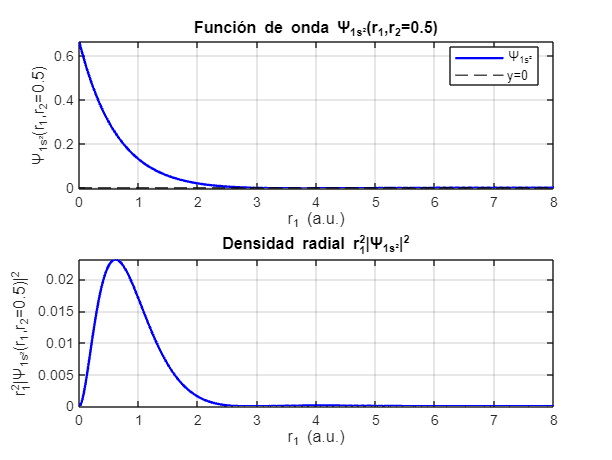

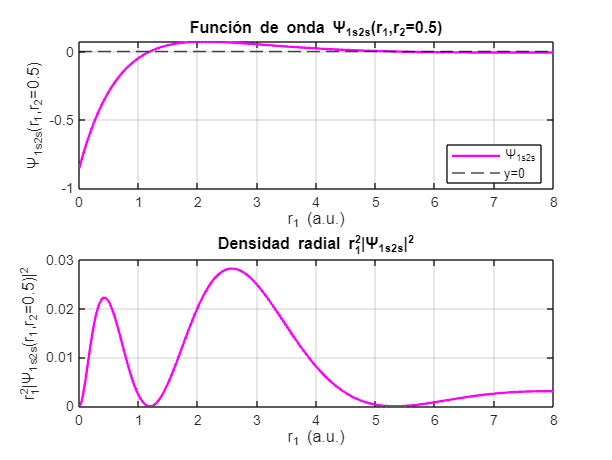

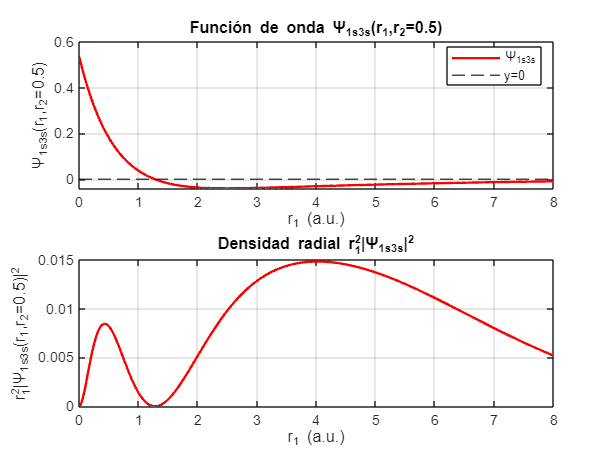

---------------------------------------------------------------------



--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HELIO (FORMA MATRICIAL) ---


--- USANDO FUNCIONES HIDROGENOIDES PARA ESTADO FUNDAMENTAL Y EXCITADOS ---



--- Paso 1: Definir funciones base ---



--- Paso 2: Matriz de solapamiento S ---


Matriz de Solapamiento S:


$$\begin{array}{l} \left(\begin{array}{cccc} \frac{2778046668940015}{281474976710656\,\pi^{2}} & 0 & \sigma_{2} & 0\\ 0 & \frac{2778046668940015}{70368744177664\,\pi } & -\frac{8334140006820045}{140737488355328\,\pi } & 0\\ \sigma_{2} & -\frac{8334140006820045}{140737488355328\,\pi } & \frac{7497947959469100485}{51298814505517056\,\pi } & \sigma_{1}\\ 0 & 0 & \sigma_{1} & \frac{2778046668940015}{70368744177664\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{5000484004092027\,\sqrt{6}}{2748779069440000\,\pi }\\ \sigma_{2}=\frac{2778046668940015}{118747255799808\,\pi^{3/2}} \end{array}$$


--- Paso 3: Matriz Hamiltoniana H ---



Matriz Hamiltoniana H:


$$\begin{array}{l} \left(\begin{array}{cccc} \frac{5\,Z\,\left(555609333788003\,Z+35184372088832\,\pi^{2}-2222437335152012\right)}{281474976710656\,\pi^{2}} & \sigma_{6} & \sigma_{5} & \sigma_{1}\\ \sigma_{6} & \frac{Z\,\left(13890233344700075\,Z+316659348799488\,\pi -55560933378800300\right)}{562949953421312\,\pi } & \sigma_{3} & \sigma_{4}\\ \sigma_{5} & \sigma_{3} & \frac{Z\,\left(26327548281544522155\,Z+132521937472585728\,\pi -144269519611392858980\right)}{410390516044136448\,\pi } & \sigma_{2}\\ \sigma_{1} & \sigma_{4} & \sigma_{2} & -\frac{555609333788003\,Z\,\left(324\,\sqrt{6}-15625\,Z+62500\right)}{395824185999360000\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2778046668940015\,\sqrt{6}\,Z\,\left(Z-2\right)}{2251799813685248\,\pi^{3/2}}\\ \sigma_{2}=-\frac{555609333788003\,\sqrt{6}\,Z\,\left(547\,Z-4442\right)}{1187472557998080000\,\pi }\\ \sigma_{3}=-\frac{2778046668940015\,Z\,\left(7429\,Z-32354\right)}{820781032088272896\,\pi }\\ \sigma_{4}=\frac{12779014677124069\,\sqrt{6}\,Z\,\left(Z-2\right)}{10995116277760000\,\pi }\\ \sigma_{5}=\frac{2778046668940015\,Z\,\left(2\,Z-11\right)}{\sigma_{7}}\\ \sigma_{6}=\frac{2778046668940015\,Z\,\left(Z-2\right)}{\sigma_{7}}\\ \sigma_{7}=474989023199232\,\pi^{3/2} \end{array}$$


--- Paso 4: Resolviendo H c = E S c ---



--- Paso 5: Optimización del parámetro Z ---



>> Nivel energético n=1:


Z óptimo para Nivel energético n=1: 2.0000


Energía óptima (Hartree): -49.300835


Energía óptima (eV): -1341.5447


Energía experimental: -2.903000 Hartree (-78.9947 eV)


Error relativo: 1598.27%


Error absoluto: 2.9030


>> Nivel energético n=2:


Z óptimo para Nivel energético n=2: 1.4343


Energía óptima (Hartree): -2.577970


Energía óptima (eV): -70.1502


Energía experimental: -2.146000 Hartree (-58.3957 eV)


Error relativo: 20.13%


Error absoluto: 2.1460


>> Nivel energético n=3:


% Convertir las funciones simbólicas a funciones de MATLAB
phi1_1s_fun = @(r,Z) sqrt(Z^3/pi) .* exp(-Z.*r);
phi1_2s_fun = @(r,Z) sqrt(Z^3/(8*pi)) .* (2-Z.*r) .* exp(-Z.*r/2);
phi1_3s_fun = @(r,Z) sqrt(Z^3/(27*pi)) .* (27-18*Z.*r+2*Z^2.*r.^2) .* exp(-Z.*r/3);

% Definir funciones para calcular las funciones de onda
psi1_fun = @(r1,r2,Z) phi1_1s_fun(r1,Z) .* phi1_1s_fun(r2,Z);
psi2_fun = @(r1,r2,Z) (phi1_1s_fun(r1,Z) .* phi1_2s_fun(r2,Z) + phi1_2s_fun(r1,Z) .* phi1_1s_fun(r2,Z))/sqrt(2);
psi3_fun = @(r1,r2,Z) (phi1_1s_fun(r1,Z) .* phi1_3s_fun(r2,Z) + phi1_3s_fun(r1,Z) .* phi1_1s_fun(r2,Z))/sqrt(2);

% Usar los valores de Z_opt y C_opt del cálculo anterior
% (estos valores deberían estar ya calculados en el código previo)
Z_opt = [1.5859, 1.9091,1.9899]; % Ejemplo, usar los valores reales calculados
C_opt = cell(1, 3);
C_opt{1} = [ 0.990734; 0.135713; 0.005346]; 
C_opt{2} = [  0.241524; -0.968958; -0.052785]; % Ejemplo para primer estado excitado
C_opt{3} = [0.0000; 0.99860; -0.050888]; % Ejemplo para segundo estado excitado

% Crear malla de puntos para visualización
r_vals = linspace(0, 10, 500);
r2_fixed = 0.5; % Valor fijo para r2 (para visualización 2D)

% Calcular funciones de onda y densidades para cada estado
Psi = zeros(3, numel(r_vals));
Dens = zeros(3, numel(r_vals));

% Para cada estado
for k = 1:3
    psi_k = zeros(size(r_vals));
    
    % Combinación lineal de funciones base
    psi_k = psi_k + C_opt{k}(1) .* psi1_fun(r_vals, r2_fixed, Z_opt(k));
    psi_k = psi_k + C_opt{k}(2) .* psi2_fun(r_vals, r2_fixed, Z_opt(k));
    psi_k = psi_k + C_opt{k}(3) .* psi3_fun(r_vals, r2_fixed, Z_opt(k));
    
    Psi(k,:) = psi_k;
    Dens(k,:) = r_vals.^2 .* psi_k.^2;
end

% Configuración para gráficas
r_lim = [0 8];
colors = {'b', 'm', 'r'};
labels = {'1s²', '1s2s', '1s3s'};
estados = {'Estado fundamental (1s²)', 'Primer estado excitado (1s2s)', 'Segundo estado excitado (1s3s)'};

% Crear figuras para cada estado
for i = 1:3
    figure; set(gcf, 'Name', estados{i}, 'NumberTitle', 'off');
    
    % Función de onda
    subplot(2,1,1);
    plot(r_vals, Psi(i,:), 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    yline(0, 'k--', 'LineWidth', 1); hold off;
    xlabel('r_1 (a.u.)'); ylabel(['\Psi_{', labels{i}, '}(r_1,r_2=', num2str(r2_fixed), ')']);
    title(['Función de onda \Psi_{', labels{i}, '}(r_1,r_2=', num2str(r2_fixed), ')']);
    legend(['\Psi_{', labels{i}, '}'], 'y=0', 'Location', 'Best'); grid on; xlim(r_lim);
    
    % Densidad de probabilidad
    subplot(2,1,2);
    plot(r_vals, Dens(i,:), 'Color', colors{i}, 'LineWidth', 1.5);
    xlabel('r_1 (a.u.)'); ylabel(['r_1^2|\Psi_{', labels{i}, '}(r_1,r_2=', num2str(r2_fixed), ')|^2']);
    title(['Densidad radial r_1^2|\Psi_{', labels{i}, '}|^2']); grid on; xlim(r_lim);
end